clear, close all;

% -------- Font Settings --------------------------------------------------
set(0,'defaultAxesFontSize',18);
set(0,'defaultAxesFontName','Times New Roman');
set(0,'defaultTextFontSize',18);
set(0,'defaultTextFontName','Times New Roman');

%%%%%%%%%%%%%%%%%%%%%
% Constellation (Tx)
%%%%%%%%%%%%%%%%%%%%%

x = [-1 1];
y = [0 0];

figure;
h = plot(x, y, 'o');
set(h, 'Linewidth', 3);
line([0 0], [-1.5 1.5], 'color', 'k');
line([-1.5 1.5], [0 0], 'color', 'k');
xlabel('Inphase','FontName','Times New Roman');
ylabel('Quadrature','FontName','Times New Roman');
text(0.9,0.2, '''1''');
text(-1.1,0.2, '''0''');
% AX = legend('Meas.', 'Sim', 2);
% LEG = findobj(AX,'type','text');
% set(LEG,'FontName', 'Times New Roman', 'FontSize',14);
grid on;
xlim([-1.5 1.5]);
ylim([-1.5 1.5]);
axis square


%%%%%%%%%%%%%%%
% Modulation
%%%%%%%%%%%%%%%

T = 100;
t = 0:T-1;
x = [1 0 1 1 0 1];
s = exp(1j*2*pi/100*t);
sym = [];
uI = [];
uQ = [];
uI0 = [];
uQ0 = [];
for ii=1:length(x)
    b = (x(ii)-1/2)*2;
    sym = [sym s*b];
    uI = [uI ones(1,T)*b];
    uQ = [uQ ones(1,T)*0];
    uI0(ii) = b;
    uQ0(ii) = 0;
end

f=figure;
f.Position = [488.0   57.8  560.0  800.2];
[ha] = tight_subplot(5,1,[.1 1],[.1 .01],[.1 .1]);

axes(ha(1));
h=stem(0:length(uI0)-1, uI0);
set(h, 'Linewidth', 2);
xlabel('index','FontName','Times New Roman');
ylabel('$$u_I$$','FontName','Times New Roman', 'interpreter', 'latex');
xlim([0 length(uI0)]);
ylim([-1.5 1.5]);
grid on
set(gca, 'xtick', 0:1:length(x));

axes(ha(2));
h=stem(0:length(uQ0)-1, uQ0);
set(h, 'Linewidth', 2);
xlabel('index','FontName','Times New Roman');
ylabel('$$u_Q$$','FontName','Times New Roman', 'interpreter', 'latex');
xlim([0 length(uQ0)]);
ylim([-1.5 1.5]);
grid on
set(gca, 'xtick', 0:1:length(x));

axes(ha(3));
h=plot((0:length(x)*T-1)/T, uI);
set(h, 'Linewidth', 2);
xlabel('$$t/T$$','FontName','Times New Roman', 'interpreter', 'latex');
ylabel('$$u_I(t)$$','FontName','Times New Roman', 'interpreter', 'latex');
%xlim([0 length(uI)]);
ylim([-1.5 1.5]);
grid on
set(gca, 'xtick', 0:1:length(x));

axes(ha(4));
h=plot((0:length(x)*T-1)/T, uQ);
set(h, 'Linewidth', 2);
xlabel('$$t/T$$','FontName','Times New Roman', 'interpreter', 'latex');
ylabel('$$u_Q(t)$$','FontName','Times New Roman', 'interpreter', 'latex');
%xlim([0 length(uQ0)]);
ylim([-1.5 1.5]);
grid on
set(gca, 'xtick', 0:1:length(x));

axes(ha(5));
h=plot((0:length(x)*T-1)/T, sym);
set(h, 'Linewidth', 2);
xlabel('$$t/T$$','FontName','Times New Roman', 'interpreter', 'latex');
ylabel('$$s(t)$$','FontName','Times New Roman', 'interpreter', 'latex');
ylim([-1.5 1.5]);
grid on
set(gca, 'xtick', 0:1:length(x));

%%%%%%%%%%%%%%%
% De-Modulation
%%%%%%%%%%%%%%%
SNR = 0;
rt = sym + 10^(-SNR/20)*randn(1,length(sym)); % SNR 6dB
rI = rt*2.*repmat(real(s),1,6);
rQ = -rt*2.*repmat(imag(s),1,6);
r_uI = [mean(rI(1:100)) mean(rI(101:200)) mean(rI(201:300)) mean(rI(3011:400)) mean(rI(401:500)) mean(rI(501:600))];
r_uQ = [mean(rQ(1:100)) mean(rQ(101:200)) mean(rQ(201:300)) mean(rQ(3011:400)) mean(rQ(401:500)) mean(rQ(501:600))];

f=figure;
f.Position = [488.0   57.8  560.0  800.2];
[ha] = tight_subplot(5,1,[.1 1],[.1 .01],[.1 .1]);

axes(ha(1));
h=plot((0:length(x)*T-1)/T, rt);
set(h, 'Linewidth', 2);
xlabel('$$t/T$$','FontName','Times New Roman', 'interpreter', 'latex');
ylabel('$$r(t)$$','FontName','Times New Roman', 'interpreter', 'latex');
ylim([-1.5 1.5]);
grid on
set(gca, 'xtick', 0:1:length(x));
% AX = legend('Meas.', 'Sim', 2);
% LEG = findobj(AX,'type','text');
% set(LEG,'FontName', 'Times New Roman', 'FontSize',14);

axes(ha(2));
h=plot((0:length(x)*T-1)/T, rI);
set(h, 'Linewidth', 2);
xlabel('$$t/T$$','FontName','Times New Roman', 'interpreter', 'latex');
ylabel('$$\hat{u}_I(t)$$','FontName','Times New Roman', 'interpreter', 'latex');
%xlim([0 length(uI)]);
ylim([-1.5 1.5]);
grid on
set(gca, 'xtick', 0:1:length(x));

axes(ha(3));
h=plot((0:length(x)*T-1)/T, rQ);
set(h, 'Linewidth', 2);
xlabel('$$t/T$$','FontName','Times New Roman', 'interpreter', 'latex');
ylabel('$$\hat u_Q(t)$$','FontName','Times New Roman', 'interpreter', 'latex');
%xlim([0 length(uQ0)]);
ylim([-1.5 1.5]);
grid on
set(gca, 'xtick', 0:1:length(x));

axes(ha(4));
h=stem(0:length(r_uI)-1, r_uI);
set(h, 'Linewidth', 2);
xlabel('index','FontName','Times New Roman');
ylabel('$$\hat{u}_I$$','FontName','Times New Roman', 'interpreter', 'latex');
xlim([0 length(r_uI)]);
ylim([-1.5 1.5]);
grid on
set(gca, 'xtick', 0:1:length(x));

axes(ha(5));
h=stem(0:length(r_uQ)-1, r_uQ);
set(h, 'Linewidth', 2);
xlabel('index','FontName','Times New Roman');
ylabel('$$\hat{u}_Q$$','FontName','Times New Roman', 'interpreter', 'latex');
xlim([0 length(r_uQ)]);
ylim([-1.5 1.5]);
grid on
set(gca, 'xtick', 0:1:length(x));


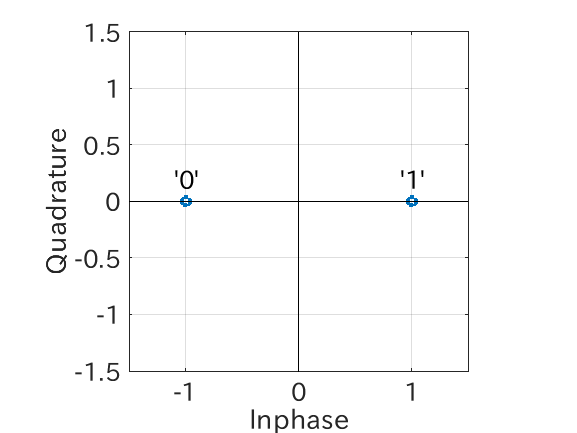

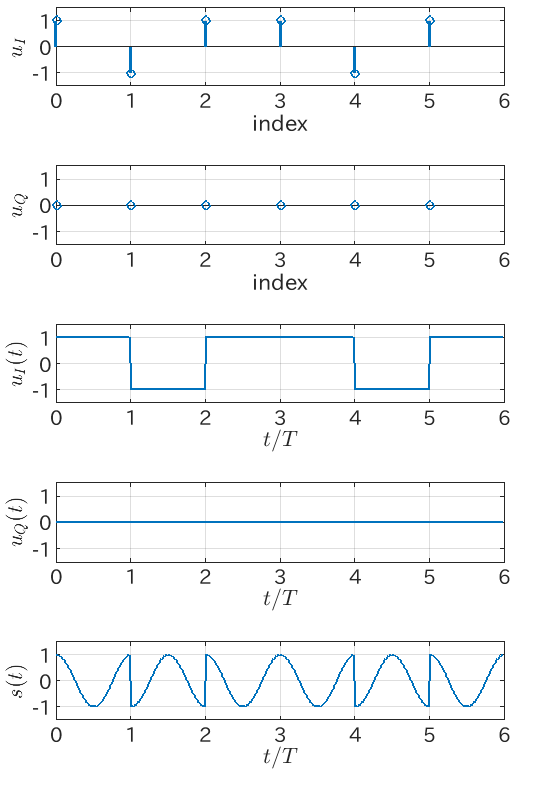

'SNR' に対する完全一致 (大文字小文字を区別) が見つかりません

最も近い候補は次のとおりです:/MATLAB/toolbox/signal/signal/snr.m の snr

%%%%%%%%%%%%%%%%%%%%%
% Constellation (Rx)
%%%%%%%%%%%%%%%%%%%%%

figure;
h = plot(r_uI, r_uQ, 'o');
set(h, 'Linewidth', 3);
line([0 0], [-1.5 1.5], 'color', 'k');
line([-1.5 1.5], [0 0], 'color', 'k');
xlabel('Inphase','FontName','Times New Roman');
ylabel('Quadrature','FontName','Times New Roman');
text(0.9,0.2, '''1''');
text(-1.1,0.2, '''0''');
% AX = legend('Meas.', 'Sim', 2);
% LEG = findobj(AX,'type','text');
% set(LEG,'FontName', 'Times New Roman', 'FontSize',14);
grid on;
xlim([-1.5 1.5]);
ylim([-1.5 1.5]);
axis square